# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

### Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex3' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

.                  ex3_companion.mat  fmincg.m           predict.m          token.mat          
..                 ex3_companion.mlx  lib                predictOneVsAll.m  
displayData.m      ex3data1.mat       lrCostFunction.m   sigmoid.m          
ex3.mlx            ex3weights.mat     oneVsAll.m         submit.m           



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

### 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/))

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

**For my data, we have a 9 unit vector and 106 iterations of this 106 X 9 matrix. We also have a 106 x vector for y that contains the training set labels. These are labeled 1 through 5.**

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

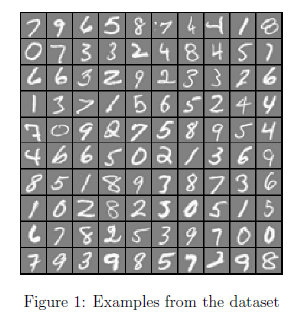                        

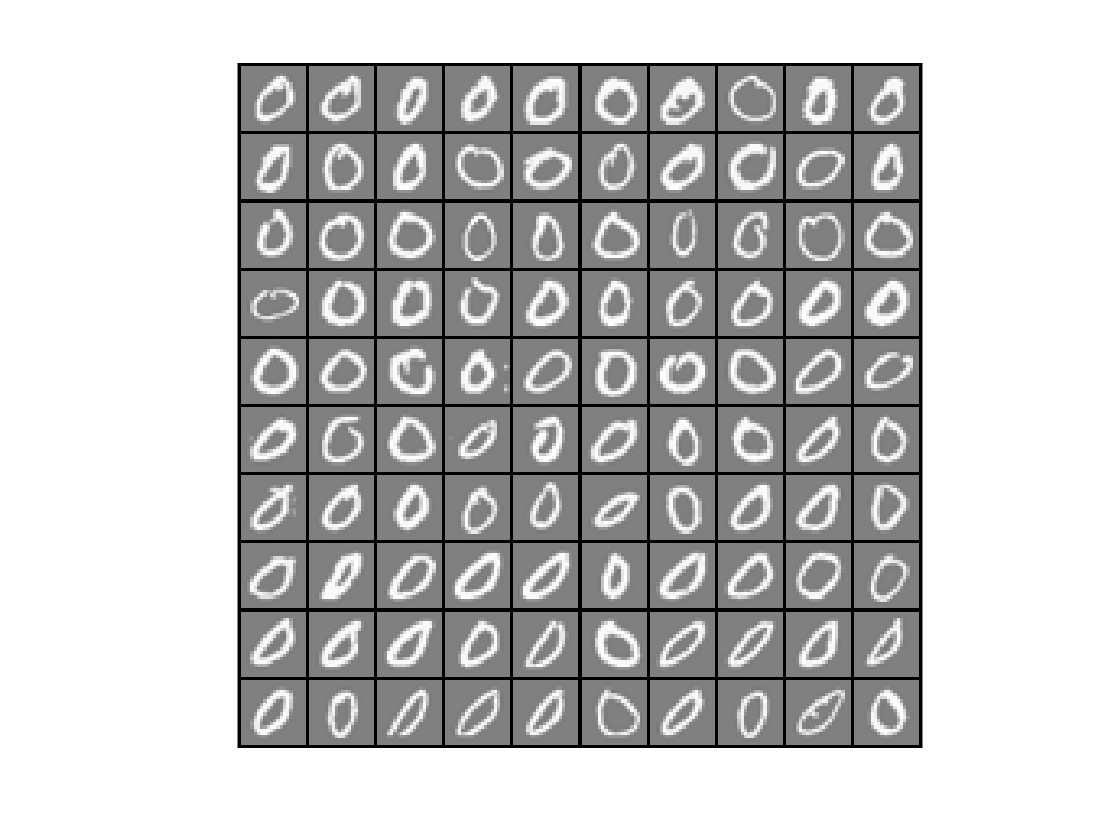

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X((1:100), :);

displayData(sel);

### 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

#### 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \;=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \;-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \;-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \;-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\;\theta^T \left(x^{\left(1\right)} \right)-\\
-{\;\theta }^T \left(x^{\left(2\right)} \right)\;-\\
\vdots \\
-{\;\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \;$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

#### 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \;} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \;} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \;} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \;} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_i \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \; & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \; & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

#### 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

h_theta =     0.6682
    0.7109
    0.7503
    0.7858
    0.8176



fprintf('Cost: %f | Expected cost: 2.534819\n',J);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('Gradients:\n'); fprintf('%f\n',grad);

Gradients:
0.146561
-0.548558
0.724722
1.398003


fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;
disp(a == b) % You should try different values of b here

   0   0   1   0   0   0   0   0   0   0



Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 5; % 10 labels, from 1 to 10 
lambda = 0.1;
y = Answersvector

y =      1
     1
     3
     3
     5
     3
     4
     4
     4
     5


[all_theta] = oneVsAll(X, y, num_labels, lambda);

h_theta =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h_theta =     0.5033
    0.4635
    0.4563
    0.4275
    0.4158
    0.4312
    0.4262
    0.4368
    0.3960
    0.4097


h_theta =     0.5100
    0.3922
    0.3716
    0.2940
    0.2649
    0.3034
    0.2907
    0.3180
    0.2199
    0.2505


Iteration     1 | Cost: 2.815111e-01


h_theta =     0.0051
    0.0297
    0.0218
    0.0245
    0.0197
    0.0148
    0.0206
    0.0195
    0.0292
    0.0182


Iteration     2 | Cost: 1.072877e-01


h_theta =     1.0000
    1.0000
    1.0000
    0.9455
    0.3163
    0.9885
    0.9322
    0.9980
    0.0004
    0.0530


h_theta =     0.7459
    0.4796
    0.3217
    0.0781
    0.0348
    0.0701
    0.0658
    0.1157
    0.0134
    0.0222


Iteration     3 | Cost: 4.335736e-02


h_theta =     0.9744
    0.0761
    0.0022
    0.0005
    0.0000
    0.0002
    0.0001
    0.0044
    0.0000
    0.0003


h_theta =     0.9097
    0.2238
    0.0348
    0.0074
    0.0010
    0.0043
    0.0033
    0.0250
    0.0004
    0.0027


Iteration     4 | Cost: 2.981587e-02


h_theta =     0.8947
    0.9229
    0.0542
    0.0033
    0.0001
    0.0004
    0.0004
    0.0146
    0.0000
    0.0002


Iteration     5 | Cost: 1.532237e-02


h_theta =     0.0378
    0.0481
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h_theta =     0.6964
    0.7595
    0.0069
    0.0003
    0.0000
    0.0000
    0.0000
    0.0024
    0.0000
    0.0000


Iteration     6 | Cost: 1.275161e-02


h_theta =     0.9957
    0.8880
    0.0119
    0.0001
    0.0000
    0.0000
    0.0000
    0.0022
    0.0000
    0.0000


Iteration     7 | Cost: 1.159386e-02


h_theta = 	1.0e+-3 *

    0.0038
    0.8724
    0.0037
    0.0046
    0.0000
    0.0001
    0.0003
    0.0030
    0.0001
    0.0003


h_theta =     0.9746
    0.7612
    0.0053
    0.0001
    0.0000
    0.0000
    0.0000
    0.0011
    0.0000
    0.0000


h_theta =     0.9860
    0.8130
    0.0070
    0.0001
    0.0000
    0.0000
    0.0000
    0.0014
    0.0000
    0.0000


Iteration     8 | Cost: 1.115702e-02


h_theta =     0.9577
    0.8512
    0.0066
    0.0001
    0.0000
    0.0000
    0.0000
    0.0011
    0.0000
    0.0000


Iteration     9 | Cost: 1.064374e-02


h_theta =     0.9923
    0.9346
    0.0194
    0.0001
    0.0000
    0.0000
    0.0000
    0.0020
    0.0000
    0.0000


h_theta =     0.9767
    0.8877
    0.0097
    0.0001
    0.0000
    0.0000
    0.0000
    0.0014
    0.0000
    0.0000


Iteration    10 | Cost: 1.051184e-02


h_theta =     0.9843
    0.8726
    0.0113
    0.0001
    0.0000
    0.0000
    0.0000
    0.0015
    0.0000
    0.0000


h_theta =     0.9924
    0.8406
    0.0150
    0.0001
    0.0000
    0.0000
    0.0000
    0.0016
    0.0000
    0.0000


Iteration    11 | Cost: 1.011631e-02


h_theta =     0.9830
    0.8610
    0.0190
    0.0002
    0.0000
    0.0000
    0.0000
    0.0013
    0.0000
    0.0000


Iteration    12 | Cost: 9.673725e-03


h_theta =     0.8174
    0.5404
    0.0060
    0.0001
    0.0000
    0.0000
    0.0000
    0.0006
    0.0000
    0.0000


h_theta =     0.9781
    0.8399
    0.0170
    0.0002
    0.0000
    0.0000
    0.0000
    0.0012
    0.0000
    0.0000


Iteration    13 | Cost: 9.622983e-03


h_theta =     0.9731
    0.8429
    0.0152
    0.0002
    0.0000
    0.0000
    0.0000
    0.0013
    0.0000
    0.0000


h_theta =     0.9671
    0.8458
    0.0136
    0.0001
    0.0000
    0.0000
    0.0000
    0.0014
    0.0000
    0.0000


Iteration    14 | Cost: 9.538965e-03


h_theta =     0.9878
    0.9200
    0.0238
    0.0002
    0.0000
    0.0000
    0.0000
    0.0027
    0.0000
    0.0000


h_theta =     0.9708
    0.8572
    0.0145
    0.0001
    0.0000
    0.0000
    0.0000
    0.0015
    0.0000
    0.0000


Iteration    15 | Cost: 9.529346e-03


h_theta =     0.9734
    0.8530
    0.0147
    0.0001
    0.0000
    0.0000
    0.0000
    0.0016
    0.0000
    0.0000


Iteration    16 | Cost: 9.514344e-03


h_theta =     0.9687
    0.8378
    0.0136
    0.0001
    0.0000
    0.0000
    0.0000
    0.0015
    0.0000
    0.0000


h_theta =     0.9705
    0.8434
    0.0140
    0.0001
    0.0000
    0.0000
    0.0000
    0.0015
    0.0000
    0.0000


Iteration    17 | Cost: 9.507862e-03


h_theta =     0.9692
    0.8450
    0.0142
    0.0002
    0.0000
    0.0000
    0.0000
    0.0015
    0.0000
    0.0000


h_theta =     0.9665
    0.8482
    0.0145
    0.0002
    0.0000
    0.0000
    0.0000
    0.0015
    0.0000
    0.0000


Iteration    18 | Cost: 9.481727e-03


h_theta =     0.9729
    0.8478
    0.0161
    0.0002
    0.0000
    0.0000
    0.0000
    0.0016
    0.0000
    0.0000


Iteration    19 | Cost: 9.454011e-03


h_theta =     0.9700
    0.8142
    0.0145
    0.0002
    0.0000
    0.0000
    0.0000
    0.0016
    0.0000
    0.0000


h_theta =     0.9719
    0.8370
    0.0155
    0.0002
    0.0000
    0.0000
    0.0000
    0.0016
    0.0000
    0.0000


Iteration    20 | Cost: 9.447365e-03


h_theta =     0.9714
    0.8321
    0.0155
    0.0002
    0.0000
    0.0000
    0.0000
    0.0017
    0.0000
    0.0000


h_theta =     0.9703
    0.8220
    0.0155
    0.0002
    0.0000
    0.0000
    0.0000
    0.0017
    0.0000
    0.0000


Iteration    21 | Cost: 9.420753e-03


h_theta =     0.9710
    0.8294
    0.0165
    0.0002
    0.0000
    0.0000
    0.0000
    0.0019
    0.0000
    0.0000


h_theta =     0.9723
    0.8435
    0.0187
    0.0002
    0.0000
    0.0000
    0.0000
    0.0021
    0.0000
    0.0000


Iteration    22 | Cost: 9.352763e-03


h_theta =     0.9582
    0.8198
    0.0192
    0.0004
    0.0000
    0.0001
    0.0001
    0.0028
    0.0000
    0.0000


h_theta =     0.9647
    0.8298
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0025
    0.0000
    0.0000


Iteration    23 | Cost: 9.317081e-03


h_theta =     0.9758
    0.8605
    0.0353
    0.0008
    0.0000
    0.0002
    0.0001
    0.0064
    0.0000
    0.0000


h_theta =     0.9660
    0.8331
    0.0202
    0.0003
    0.0000
    0.0001
    0.0001
    0.0028
    0.0000
    0.0000


Iteration    24 | Cost: 9.314832e-03


h_theta =     0.9654
    0.8218
    0.0208
    0.0004
    0.0000
    0.0001
    0.0001
    0.0031
    0.0000
    0.0000


h_theta =     0.9658
    0.8296
    0.0204
    0.0004
    0.0000
    0.0001
    0.0001
    0.0029
    0.0000
    0.0000


Iteration    25 | Cost: 9.313724e-03


h_theta =     0.9649
    0.8269
    0.0200
    0.0003
    0.0000
    0.0001
    0.0001
    0.0028
    0.0000
    0.0000


Iteration    26 | Cost: 9.312283e-03


h_theta =     0.9648
    0.8285
    0.0200
    0.0003
    0.0000
    0.0001
    0.0001
    0.0028
    0.0000
    0.0000


h_theta =     0.9648
    0.8316
    0.0201
    0.0003
    0.0000
    0.0001
    0.0001
    0.0028
    0.0000
    0.0000


Iteration    27 | Cost: 9.307791e-03


h_theta =     0.9641
    0.8264
    0.0195
    0.0003
    0.0000
    0.0001
    0.0001
    0.0027
    0.0000
    0.0000


Iteration    28 | Cost: 9.303801e-03


h_theta = 10×1
    0.9663
    0.8288
    0.0197
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    29 | Cost: 9.299959e-03


h_theta = 10×1
    0.9613
    0.8342
    0.0168
    0.0003
    0.0000
    0.0001
    0.0000
    0.0026
    0.0000
    0.0000


h_theta = 10×1
    0.9652
    0.8300
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0027
    0.0000
    0.0000


Iteration    30 | Cost: 9.299202e-03


h_theta = 10×1
    0.9664
    0.8271
    0.0183
    0.0003
    0.0000
    0.0001
    0.0000
    0.0027
    0.0000
    0.0000


h_theta = 10×1
    0.9656
    0.8289
    0.0187
    0.0003
    0.0000
    0.0001
    0.0000
    0.0027
    0.0000
    0.0000


Iteration    31 | Cost: 9.298917e-03


h_theta = 10×1
    0.9672
    0.8324
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9660
    0.8298
    0.0188
    0.0003
    0.0000
    0.0001
    0.0000
    0.0027
    0.0000
    0.0000


Iteration    32 | Cost: 9.298846e-03


h_theta = 10×1
    0.9662
    0.8294
    0.0189
    0.0003
    0.0000
    0.0001
    0.0000
    0.0027
    0.0000
    0.0000


h_theta = 10×1
    0.9663
    0.8288
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0027
    0.0000
    0.0000


Iteration    33 | Cost: 9.298675e-03


h_theta = 10×1
    0.9660
    0.8310
    0.0194
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9662
    0.8294
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    34 | Cost: 9.298625e-03


h_theta = 10×1
    0.9657
    0.8288
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    35 | Cost: 9.298599e-03


h_theta = 10×1
    0.9641
    0.8296
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9655
    0.8289
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9656
    0.8289
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    36 | Cost: 9.298596e-03


h_theta = 10×1
    0.9656
    0.8289
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9657
    0.8290
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9659
    0.8293
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    37 | Cost: 9.298565e-03


h_theta = 10×1
    0.9660
    0.8287
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    38 | Cost: 9.298540e-03


h_theta = 10×1
    0.9662
    0.8290
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    39 | Cost: 9.298513e-03


h_theta = 10×1
    0.9660
    0.8290
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9657
    0.8290
    0.0189
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    40 | Cost: 9.298449e-03


h_theta = 10×1
    0.9659
    0.8309
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9658
    0.8295
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    41 | Cost: 9.298435e-03


h_theta = 10×1
    0.9658
    0.8293
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9657
    0.8290
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    42 | Cost: 9.298374e-03


h_theta = 10×1
    0.9655
    0.8248
    0.0188
    0.0003
    0.0000
    0.0001
    0.0000
    0.0027
    0.0000
    0.0000


h_theta = 10×1
    0.9657
    0.8286
    0.0190
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9657
    0.8289
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    43 | Cost: 9.298372e-03


h_theta = 10×1
    0.9657
    0.8289
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9658
    0.8289
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9659
    0.8288
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    44 | Cost: 9.298358e-03


h_theta = 10×1
    0.9656
    0.8279
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9658
    0.8286
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    45 | Cost: 9.298354e-03


h_theta = 10×1
    0.9657
    0.8287
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    46 | Cost: 9.298350e-03


h_theta = 10×1
    0.9658
    0.8288
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9658
    0.8289
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    47 | Cost: 9.298341e-03


h_theta = 10×1
    0.9658
    0.8286
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    48 | Cost: 9.298330e-03


h_theta = 10×1
    0.9655
    0.8284
    0.0191
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9657
    0.8285
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    49 | Cost: 9.298326e-03


h_theta = 10×1
    0.9657
    0.8291
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


h_theta = 10×1
    0.9657
    0.8286
    0.0192
    0.0003
    0.0000
    0.0001
    0.0000
    0.0028
    0.0000
    0.0000


Iteration    50 | Cost: 9.298325e-03


h_theta = 10×1
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h_theta = 10×1
    0.3786
    0.3796
    0.3985
    0.3996
    0.4281
    0.4208
    0.4125
    0.4016
    0.4134
    0.4139


h_theta = 10×1
    0.1845
    0.1865
    0.2253
    0.2276
    0.2954
    0.2771
    0.2570
    0.2321
    0.2593
    0.2604


Iteration     1 | Cost: 3.138986e-01


h_theta = 10×1
    0.0380
    0.0141
    0.0101
    0.0152
    0.0140
    0.0169
    0.0135
    0.0215
    0.0144
    0.0262


Iteration     2 | Cost: 1.681510e-01


h_theta = 10×1
    0.0000
    0.0000
    0.0008
    0.0013
    1.0000
    0.9960
    0.6990
    0.0017
    0.7813
    0.6787


h_theta = 10×1
    0.0046
    0.0032
    0.0077
    0.0118
    0.0613
    0.0449
    0.0230
    0.0165
    0.0254
    0.0409


Iteration     3 | Cost: 1.304029e-01


h_theta = 10×1
    0.0001
    0.0000
    0.0008
    0.0069
    0.6777
    0.4013
    0.0602
    0.0148
    0.1408
    0.3580


h_theta = 10×1
    0.0032
    0.0020
    0.0062
    0.0112
    0.0846
    0.0578
    0.0253
    0.0163
    0.0304
    0.0522


Iteration     4 | Cost: 1.272044e-01


h_theta = 10×1
    0.0008
    0.0007
    0.0022
    0.0066
    0.0570
    0.0382
    0.0138
    0.0084
    0.0209
    0.0378


Iteration     5 | Cost: 1.233905e-01


h_theta = 10×1
    0.0068
    0.0001
    0.0019
    0.0038
    0.1598
    0.1083
    0.0192
    0.0121
    0.0224
    0.0501


h_theta = 10×1
    0.0018
    0.0003
    0.0020
    0.0054
    0.0841
    0.0563
    0.0156
    0.0096
    0.0215
    0.0419


Iteration     6 | Cost: 1.224184e-01


h_theta = 10×1
    0.0009
    0.0002
    0.0010
    0.0042
    0.0572
    0.0363
    0.0103
    0.0067
    0.0214
    0.0324


Iteration     7 | Cost: 1.212201e-01


h_theta = 10×1
    0.0003
    0.0001
    0.0006
    0.0042
    0.0617
    0.0370
    0.0095
    0.0055
    0.0264
    0.0326


h_theta = 10×1
    0.0006
    0.0001
    0.0008
    0.0042
    0.0591
    0.0366
    0.0099
    0.0062
    0.0234
    0.0325


Iteration     8 | Cost: 1.207617e-01


h_theta = 10×1
    0.0006
    0.0001
    0.0007
    0.0050
    0.0490
    0.0350
    0.0090
    0.0060
    0.0224
    0.0296


Iteration     9 | Cost: 1.202490e-01


h_theta = 10×1
    0.0014
    0.0002
    0.0009
    0.0051
    0.0407
    0.0321
    0.0084
    0.0074
    0.0183
    0.0268


h_theta = 10×1
    0.0007
    0.0001
    0.0008
    0.0050
    0.0473
    0.0344
    0.0089
    0.0063
    0.0215
    0.0290


Iteration    10 | Cost: 1.201716e-01


h_theta = 10×1
    0.0009
    0.0001
    0.0009
    0.0051
    0.0535
    0.0383
    0.0096
    0.0072
    0.0220
    0.0308


Iteration    11 | Cost: 1.200649e-01


h_theta = 10×1
    0.0007
    0.0001
    0.0008
    0.0052
    0.0549
    0.0374
    0.0095
    0.0071
    0.0240
    0.0315


h_theta = 10×1
    0.0008
    0.0001
    0.0008
    0.0051
    0.0541
    0.0379
    0.0095
    0.0071
    0.0229
    0.0311


Iteration    12 | Cost: 1.200269e-01


h_theta = 10×1
    0.0007
    0.0001
    0.0008
    0.0052
    0.0505
    0.0352
    0.0091
    0.0071
    0.0231
    0.0303


Iteration    13 | Cost: 1.199729e-01


h_theta = 10×1
    0.0009
    0.0002
    0.0008
    0.0054
    0.0499
    0.0362
    0.0092
    0.0076
    0.0224
    0.0304


Iteration    14 | Cost: 1.199486e-01


h_theta = 10×1
    0.0012
    0.0002
    0.0010
    0.0059
    0.0536
    0.0409
    0.0099
    0.0087
    0.0224
    0.0321


h_theta = 10×1
    0.0011
    0.0002
    0.0009
    0.0057
    0.0520
    0.0388
    0.0096
    0.0082
    0.0224
    0.0314


Iteration    15 | Cost: 1.199272e-01


h_theta = 10×1
    0.0010
    0.0002
    0.0009
    0.0057
    0.0528
    0.0389
    0.0096
    0.0082
    0.0228
    0.0316


h_theta = 10×1
    0.0010
    0.0002
    0.0009
    0.0057
    0.0536
    0.0390
    0.0096
    0.0081
    0.0233
    0.0318


Iteration    16 | Cost: 1.198833e-01


h_theta = 10×1
    0.0008
    0.0002
    0.0008
    0.0056
    0.0488
    0.0346
    0.0089
    0.0077
    0.0238
    0.0303


Iteration    17 | Cost: 1.198470e-01


h_theta = 10×1
    0.0009
    0.0002
    0.0008
    0.0058
    0.0466
    0.0338
    0.0087
    0.0082
    0.0236
    0.0297


Iteration    18 | Cost: 1.198067e-01


h_theta = 10×1
    0.0010
    0.0002
    0.0008
    0.0060
    0.0488
    0.0357
    0.0089
    0.0087
    0.0242
    0.0305


Iteration    19 | Cost: 1.197442e-01


h_theta = 10×1
    0.0004
    0.0001
    0.0008
    0.0055
    0.0658
    0.0433
    0.0105
    0.0068
    0.0272
    0.0348


h_theta = 10×1
    0.0009
    0.0002
    0.0008
    0.0059
    0.0503
    0.0364
    0.0090
    0.0085
    0.0245
    0.0309


h_theta = 10×1
    0.0010
    0.0002
    0.0008
    0.0060
    0.0491
    0.0358
    0.0089
    0.0086
    0.0243
    0.0306


Iteration    20 | Cost: 1.197434e-01


h_theta = 10×1
    0.0010
    0.0002
    0.0008
    0.0060
    0.0493
    0.0360
    0.0089
    0.0086
    0.0243
    0.0306


h_theta = 10×1
    0.0010
    0.0002
    0.0008
    0.0060
    0.0496
    0.0362
    0.0089
    0.0087
    0.0244
    0.0307


Iteration    21 | Cost: 1.197398e-01


h_theta = 10×1
    0.0010
    0.0002
    0.0008
    0.0060
    0.0492
    0.0362
    0.0089
    0.0086
    0.0242
    0.0306


h_theta = 10×1
    0.0010
    0.0002
    0.0008
    0.0061
    0.0484
    0.0361
    0.0088
    0.0086
    0.0240
    0.0303


Iteration    22 | Cost: 1.197320e-01


h_theta = 10×1
    0.0009
    0.0001
    0.0007
    0.0060
    0.0488
    0.0363
    0.0087
    0.0085
    0.0242
    0.0302


h_theta = 10×1
    0.0010
    0.0001
    0.0008
    0.0061
    0.0487
    0.0362
    0.0088
    0.0085
    0.0241
    0.0302


Iteration    23 | Cost: 1.197277e-01


h_theta = 10×1
    0.0009
    0.0001
    0.0007
    0.0060
    0.0480
    0.0356
    0.0086
    0.0084
    0.0240
    0.0298


h_theta = 10×1
    0.0009
    0.0001
    0.0007
    0.0059
    0.0472
    0.0348
    0.0084
    0.0083
    0.0240
    0.0293


Iteration    24 | Cost: 1.197181e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0058
    0.0490
    0.0364
    0.0085
    0.0087
    0.0237
    0.0298


h_theta = 10×1
    0.0009
    0.0001
    0.0007
    0.0059
    0.0479
    0.0354
    0.0084
    0.0084
    0.0239
    0.0295


Iteration    25 | Cost: 1.197146e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0059
    0.0501
    0.0368
    0.0087
    0.0087
    0.0243
    0.0302


h_theta = 10×1
    0.0009
    0.0001
    0.0007
    0.0059
    0.0485
    0.0357
    0.0085
    0.0085
    0.0240
    0.0297


Iteration    26 | Cost: 1.197136e-01


h_theta = 10×1
    0.0009
    0.0001
    0.0007
    0.0059
    0.0483
    0.0356
    0.0085
    0.0086
    0.0241
    0.0297


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0353
    0.0085
    0.0087
    0.0244
    0.0298


Iteration    27 | Cost: 1.197103e-01


h_theta = 10×1
    0.0011
    0.0002
    0.0008
    0.0063
    0.0475
    0.0359
    0.0086
    0.0091
    0.0241
    0.0300


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0479
    0.0354
    0.0085
    0.0087
    0.0243
    0.0298


Iteration    28 | Cost: 1.197098e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0483
    0.0359
    0.0086
    0.0089
    0.0244
    0.0300


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0482
    0.0357
    0.0086
    0.0088
    0.0244
    0.0299


Iteration    29 | Cost: 1.197095e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0480
    0.0354
    0.0085
    0.0088
    0.0245
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0481
    0.0356
    0.0085
    0.0088
    0.0244
    0.0299


Iteration    30 | Cost: 1.197093e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0478
    0.0353
    0.0085
    0.0088
    0.0244
    0.0298


Iteration    31 | Cost: 1.197093e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0476
    0.0350
    0.0085
    0.0088
    0.0243
    0.0297


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0477
    0.0352
    0.0085
    0.0088
    0.0244
    0.0298


Iteration    32 | Cost: 1.197092e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0478
    0.0352
    0.0085
    0.0088
    0.0244
    0.0298


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0479
    0.0353
    0.0085
    0.0088
    0.0244
    0.0298


Iteration    33 | Cost: 1.197089e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0481
    0.0356
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    34 | Cost: 1.197088e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0483
    0.0356
    0.0086
    0.0088
    0.0244
    0.0300


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0481
    0.0355
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    35 | Cost: 1.197088e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0481
    0.0355
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0355
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0479
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    36 | Cost: 1.197086e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0482
    0.0356
    0.0086
    0.0088
    0.0244
    0.0299


Iteration    37 | Cost: 1.197085e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0477
    0.0353
    0.0085
    0.0088
    0.0242
    0.0296


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0482
    0.0355
    0.0086
    0.0088
    0.0244
    0.0298


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0482
    0.0356
    0.0086
    0.0088
    0.0244
    0.0299


Iteration    38 | Cost: 1.197085e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0482
    0.0355
    0.0086
    0.0088
    0.0244
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0481
    0.0355
    0.0085
    0.0088
    0.0244
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    39 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0481
    0.0354
    0.0085
    0.0088
    0.0243
    0.0300


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    40 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    41 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0481
    0.0355
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    42 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0061
    0.0482
    0.0355
    0.0085
    0.0088
    0.0244
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    43 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    44 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    45 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0481
    0.0355
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0481
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    46 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    47 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    48 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    49 | Cost: 1.197084e-01


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0481
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


h_theta = 10×1
    0.0010
    0.0001
    0.0007
    0.0060
    0.0480
    0.0354
    0.0085
    0.0088
    0.0243
    0.0299


Iteration    50 | Cost: 1.197084e-01


h_theta = 10×1
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h_theta = 10×1
    0.4355
    0.4748
    0.4581
    0.4564
    0.4473
    0.4445
    0.4514
    0.4581
    0.4528
    0.4503


h_theta = 10×1
    0.3148
    0.4250
    0.3765
    0.3718
    0.3464
    0.3388
    0.3578
    0.3765
    0.3617
    0.3548


Iteration     1 | Cost: 5.984210e-01


h_theta = 10×1
    0.7781
    0.4462
    0.5274
    0.1918
    0.5371
    0.6047
    0.3826
    0.4504
    0.0907
    0.3190


h_theta = 10×1
    0.4493
    0.4310
    0.4180
    0.3137
    0.3981
    0.4110
    0.3648
    0.3970
    0.2575
    0.3445


Iteration     2 | Cost: 5.854669e-01


h_theta = 10×1
    0.0722
    0.3018
    0.1678
    0.2141
    0.1694
    0.1477
    0.1792
    0.2282
    0.2179
    0.2362


h_theta = 10×1
    0.2034
    0.3647
    0.2771
    0.2614
    0.2699
    0.2596
    0.2626
    0.3071
    0.2374
    0.2879


Iteration     3 | Cost: 5.754835e-01


h_theta = 10×1
    0.1863
    0.7262
    0.5468
    0.5039
    0.3253
    0.3515
    0.4139
    0.4257
    0.3361
    0.3187


h_theta = 10×1
    0.1991
    0.4567
    0.3378
    0.3152
    0.2832
    0.2810
    0.2969
    0.3350
    0.2600
    0.2954


Iteration     4 | Cost: 5.728502e-01


h_theta = 10×1
    0.3404
    0.4665
    0.3996
    0.3422
    0.3108
    0.3436
    0.3413
    0.3665
    0.2598
    0.3111


h_theta = 10×1
    0.2741
    0.4623
    0.3727
    0.3305
    0.2988
    0.3160
    0.3219
    0.3529
    0.2599
    0.3043


Iteration     5 | Cost: 5.713943e-01


h_theta = 10×1
    0.2267
    0.3823
    0.3450
    0.3132
    0.3072
    0.3224
    0.3218
    0.3228
    0.2642
    0.2975


Iteration     6 | Cost: 5.697594e-01


h_theta = 10×1
    0.1446
    0.4647
    0.3370
    0.3197
    0.2518
    0.2630
    0.2849
    0.3079
    0.2320
    0.2589


h_theta = 10×1
    0.1819
    0.4232
    0.3410
    0.3164
    0.2785
    0.2917
    0.3029
    0.3152
    0.2477
    0.2777


Iteration     7 | Cost: 5.690357e-01


h_theta = 10×1
    0.2202
    0.4873
    0.3644
    0.3172
    0.2786
    0.2965
    0.2996
    0.3490
    0.2179
    0.2800


h_theta = 10×1
    0.1984
    0.4518
    0.3514
    0.3168
    0.2786
    0.2938
    0.3015
    0.3302
    0.2340
    0.2787


Iteration     8 | Cost: 5.687097e-01


h_theta = 10×1
    0.1844
    0.4285
    0.3406
    0.3072
    0.2929
    0.3004
    0.3016
    0.3327
    0.2338
    0.2848


Iteration     9 | Cost: 5.683125e-01


h_theta = 10×1
    0.1539
    0.3906
    0.3170
    0.3099
    0.2752
    0.2819
    0.2922
    0.3117
    0.2460
    0.2723


h_theta = 10×1
    0.1666
    0.4069
    0.3271
    0.3087
    0.2828
    0.2898
    0.2962
    0.3207
    0.2407
    0.2777


Iteration    10 | Cost: 5.681273e-01


h_theta = 10×1
    0.1807
    0.4050
    0.3408
    0.3234
    0.2871
    0.3009
    0.3066
    0.3247
    0.2483
    0.2752


Iteration    11 | Cost: 5.679168e-01


h_theta = 10×1
    0.2061
    0.4073
    0.3464
    0.3196
    0.3004
    0.3125
    0.3102
    0.3420
    0.2441
    0.2831


Iteration    12 | Cost: 5.678108e-01


h_theta = 10×1
    0.1967
    0.3897
    0.3251
    0.3024
    0.3155
    0.3091
    0.2993
    0.3611
    0.2403
    0.2915


h_theta = 10×1
    0.2031
    0.4017
    0.3395
    0.3141
    0.3052
    0.3114
    0.3067
    0.3481
    0.2429
    0.2858


Iteration    13 | Cost: 5.677514e-01


h_theta = 10×1
    0.1934
    0.3998
    0.3353
    0.3139
    0.3018
    0.3067
    0.3040
    0.3449
    0.2437
    0.2837


h_theta = 10×1
    0.1752
    0.3962
    0.3271
    0.3135
    0.2952
    0.2974
    0.2987
    0.3384
    0.2455
    0.2796


Iteration    14 | Cost: 5.675724e-01


h_theta = 10×1
    0.1898
    0.4356
    0.3455
    0.3389
    0.2728
    0.2895
    0.2986
    0.3424
    0.2432
    0.2664


h_theta = 10×1
    0.1791
    0.4070
    0.3322
    0.3204
    0.2889
    0.2952
    0.2987
    0.3395
    0.2448
    0.2759


Iteration    15 | Cost: 5.675233e-01


h_theta = 10×1
    0.1881
    0.3925
    0.3342
    0.3244
    0.2954
    0.3046
    0.3045
    0.3407
    0.2502
    0.2773


Iteration    16 | Cost: 5.674841e-01


h_theta = 10×1
    0.1871
    0.3713
    0.3226
    0.3238
    0.2914
    0.3008
    0.3010
    0.3380
    0.2555
    0.2758


h_theta = 10×1
    0.1875
    0.3801
    0.3274
    0.3241
    0.2931
    0.3024
    0.3025
    0.3391
    0.2533
    0.2765


Iteration    17 | Cost: 5.674555e-01


h_theta = 10×1
    0.1846
    0.3856
    0.3274
    0.3251
    0.2918
    0.2997
    0.3011
    0.3417
    0.2530
    0.2759


h_theta = 10×1
    0.1795
    0.3954
    0.3274
    0.3269
    0.2897
    0.2950
    0.2985
    0.3465
    0.2526
    0.2750


Iteration    18 | Cost: 5.673761e-01


h_theta = 10×1
    0.1928
    0.4011
    0.3349
    0.3252
    0.3033
    0.3056
    0.3023
    0.3618
    0.2485
    0.2789


h_theta = 10×1
    0.1843
    0.3975
    0.3301
    0.3263
    0.2947
    0.2989
    0.2999
    0.3521
    0.2511
    0.2764


Iteration    19 | Cost: 5.673472e-01


h_theta = 10×1
    0.1823
    0.3791
    0.3172
    0.3180
    0.2917
    0.2942
    0.2934
    0.3485
    0.2489
    0.2752


h_theta = 10×1
    0.1834
    0.3887
    0.3240
    0.3223
    0.2933
    0.2967
    0.2968
    0.3504
    0.2501
    0.2758


Iteration    20 | Cost: 5.673335e-01


h_theta = 10×1
    0.1786
    0.3809
    0.3201
    0.3235
    0.2924
    0.2960
    0.2963
    0.3478
    0.2527
    0.2749


Iteration    21 | Cost: 5.673224e-01


h_theta = 10×1
    0.1836
    0.3822
    0.3232
    0.3292
    0.2916
    0.2983
    0.2984
    0.3502
    0.2546
    0.2743


Iteration    22 | Cost: 5.673141e-01


h_theta = 10×1
    0.1898
    0.3864
    0.3255
    0.3287
    0.2925
    0.2989
    0.2983
    0.3550
    0.2526
    0.2745


h_theta = 10×1
    0.1872
    0.3847
    0.3245
    0.3289
    0.2921
    0.2986
    0.2984
    0.3530
    0.2534
    0.2744


Iteration    23 | Cost: 5.673061e-01


h_theta = 10×1
    0.1832
    0.3830
    0.3230
    0.3270
    0.2938
    0.2980
    0.2977
    0.3533
    0.2535
    0.2745


Iteration    24 | Cost: 5.672975e-01


h_theta = 10×1
    0.1730
    0.3932
    0.3149
    0.3246
    0.2808
    0.2829
    0.2875
    0.3525
    0.2488
    0.2703


h_theta = 10×1
    0.1821
    0.3840
    0.3222
    0.3268
    0.2925
    0.2964
    0.2967
    0.3532
    0.2530
    0.2741


Iteration    25 | Cost: 5.672970e-01


h_theta = 10×1
    0.1807
    0.3880
    0.3222
    0.3272
    0.2911
    0.2947
    0.2956
    0.3543
    0.2520
    0.2736


h_theta = 10×1
    0.1818
    0.3851
    0.3222
    0.3269
    0.2921
    0.2960
    0.2964
    0.3535
    0.2528
    0.2739


Iteration    26 | Cost: 5.672968e-01


h_theta = 10×1
    0.1819
    0.3851
    0.3224
    0.3269
    0.2924
    0.2963
    0.2966
    0.3536
    0.2528
    0.2740


h_theta = 10×1
    0.1822
    0.3851
    0.3228
    0.3271
    0.2929
    0.2968
    0.2969
    0.3538
    0.2529
    0.2742


Iteration    27 | Cost: 5.672959e-01


h_theta = 10×1
    0.1829
    0.3830
    0.3223
    0.3268
    0.2932
    0.2974
    0.2971
    0.3534
    0.2531
    0.2743


Iteration    28 | Cost: 5.672953e-01


h_theta = 10×1
    0.1829
    0.3828
    0.3228
    0.3275
    0.2935
    0.2979
    0.2976
    0.3533
    0.2536
    0.2743


Iteration    29 | Cost: 5.672946e-01


h_theta = 10×1
    0.1829
    0.3834
    0.3228
    0.3278
    0.2927
    0.2974
    0.2974
    0.3532
    0.2536
    0.2741


Iteration    30 | Cost: 5.672937e-01


h_theta = 10×1
    0.1828
    0.3835
    0.3227
    0.3274
    0.2930
    0.2974
    0.2973
    0.3534
    0.2534
    0.2742


h_theta = 10×1
    0.1827
    0.3838
    0.3226
    0.3268
    0.2935
    0.2974
    0.2971
    0.3539
    0.2529
    0.2743


Iteration    31 | Cost: 5.672912e-01


h_theta = 10×1
    0.1802
    0.3838
    0.3211
    0.3264
    0.2921
    0.2955
    0.2959
    0.3532
    0.2528
    0.2739


Iteration    32 | Cost: 5.672892e-01


h_theta = 10×1
    0.1791
    0.3847
    0.3209
    0.3267
    0.2916
    0.2949
    0.2955
    0.3533
    0.2528
    0.2737


h_theta = 10×1
    0.1776
    0.3860
    0.3205
    0.3271
    0.2909
    0.2939
    0.2949
    0.3535
    0.2528
    0.2734


Iteration    33 | Cost: 5.672845e-01


h_theta = 10×1
    0.1795
    0.3869
    0.3219
    0.3278
    0.2919
    0.2953
    0.2958
    0.3547
    0.2527
    0.2738


h_theta = 10×1
    0.1820
    0.3881
    0.3237
    0.3287
    0.2932
    0.2972
    0.2969
    0.3562
    0.2526
    0.2742


Iteration    34 | Cost: 5.672738e-01


h_theta = 10×1
    0.1825
    0.3756
    0.3178
    0.3249
    0.2925
    0.2964
    0.2950
    0.3529
    0.2530
    0.2738


h_theta = 10×1
    0.1822
    0.3829
    0.3212
    0.3271
    0.2929
    0.2969
    0.2961
    0.3548
    0.2528
    0.2740


Iteration    35 | Cost: 5.672693e-01


h_theta = 10×1
    0.1744
    0.3742
    0.3191
    0.3275
    0.2948
    0.2973
    0.2974
    0.3507
    0.2573
    0.2733


h_theta = 10×1
    0.1812
    0.3818
    0.3210
    0.3271
    0.2931
    0.2969
    0.2963
    0.3543
    0.2533
    0.2740


Iteration    36 | Cost: 5.672688e-01


h_theta = 10×1
    0.1821
    0.3833
    0.3225
    0.3285
    0.2930
    0.2973
    0.2971
    0.3546
    0.2540
    0.2737


h_theta = 10×1
    0.1817
    0.3827
    0.3218
    0.3279
    0.2931
    0.2971
    0.2967
    0.3545
    0.2537
    0.2738


Iteration    37 | Cost: 5.672685e-01


h_theta = 10×1
    0.1833
    0.3822
    0.3221
    0.3278
    0.2932
    0.2975
    0.2970
    0.3546
    0.2538
    0.2740


h_theta = 10×1
    0.1824
    0.3825
    0.3220
    0.3279
    0.2931
    0.2973
    0.2968
    0.3545
    0.2538
    0.2739


Iteration    38 | Cost: 5.672684e-01


h_theta = 10×1
    0.1824
    0.3821
    0.3220
    0.3278
    0.2934
    0.2975
    0.2970
    0.3545
    0.2539
    0.2740


Iteration    39 | Cost: 5.672682e-01


h_theta = 10×1
    0.1818
    0.3827
    0.3218
    0.3278
    0.2930
    0.2971
    0.2968
    0.3544
    0.2538
    0.2739


Iteration    40 | Cost: 5.672680e-01


h_theta = 10×1
    0.1822
    0.3839
    0.3219
    0.3278
    0.2925
    0.2968
    0.2965
    0.3546
    0.2533
    0.2739


h_theta = 10×1
    0.1820
    0.3833
    0.3219
    0.3278
    0.2928
    0.2969
    0.2966
    0.3545
    0.2536
    0.2739


Iteration    41 | Cost: 5.672680e-01


h_theta = 10×1
    0.1822
    0.3831
    0.3218
    0.3277
    0.2929
    0.2971
    0.2966
    0.3545
    0.2535
    0.2740


Iteration    42 | Cost: 5.672679e-01


h_theta = 10×1
    0.1818
    0.3822
    0.3215
    0.3275
    0.2930
    0.2970
    0.2966
    0.3541
    0.2538
    0.2740


h_theta = 10×1
    0.1820
    0.3827
    0.3217
    0.3276
    0.2929
    0.2971
    0.2966
    0.3543
    0.2537
    0.2740


Iteration    43 | Cost: 5.672678e-01


h_theta = 10×1
    0.1823
    0.3827
    0.3219
    0.3277
    0.2931
    0.2973
    0.2968
    0.3543
    0.2538
    0.2740


Iteration    44 | Cost: 5.672678e-01


h_theta = 10×1
    0.1824
    0.3832
    0.3221
    0.3278
    0.2930
    0.2972
    0.2968
    0.3544
    0.2537
    0.2740


Iteration    45 | Cost: 5.672678e-01


h_theta = 10×1
    0.1821
    0.3834
    0.3220
    0.3277
    0.2928
    0.2970
    0.2967
    0.3543
    0.2535
    0.2740


Iteration    46 | Cost: 5.672677e-01


h_theta = 10×1
    0.1821
    0.3831
    0.3219
    0.3276
    0.2929
    0.2971
    0.2967
    0.3542
    0.2536
    0.2741


Iteration    47 | Cost: 5.672677e-01


h_theta = 10×1
    0.1828
    0.3832
    0.3224
    0.3278
    0.2932
    0.2975
    0.2971
    0.3544
    0.2537
    0.2742


h_theta = 10×1
    0.1824
    0.3831
    0.3220
    0.3276
    0.2930
    0.2972
    0.2968
    0.3543
    0.2536
    0.2741


Iteration    48 | Cost: 5.672677e-01


h_theta = 10×1
    0.1823
    0.3830
    0.3221
    0.3277
    0.2930
    0.2973
    0.2969
    0.3542
    0.2537
    0.2741


Iteration    49 | Cost: 5.672676e-01


h_theta = 10×1
    0.1821
    0.3831
    0.3220
    0.3276
    0.2929
    0.2971
    0.2968
    0.3541
    0.2536
    0.2740


Iteration    50 | Cost: 5.672676e-01


h_theta = 10×1
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h_theta = 10×1
    0.4617
    0.4633
    0.4145
    0.4309
    0.3729
    0.3839
    0.3994
    0.4300
    0.4104
    0.4151


h_theta = 10×1
    0.3869
    0.3915
    0.2620
    0.3027
    0.1738
    0.1948
    0.2272
    0.3004
    0.2523
    0.2633


Iteration     1 | Cost: 5.312372e-01


h_theta = 10×1
    0.0044
    0.0947
    0.2204
    0.1492
    0.4146
    0.2485
    0.2245
    0.0919
    0.2020
    0.0910


h_theta = 10×1
    0.1698
    0.2985
    0.2521
    0.2610
    0.2171
    0.2062
    0.2266
    0.2361
    0.2401
    0.2111


h_theta = 10×1
    0.2458
    0.3355
    0.2561
    0.2778
    0.1983
    0.2014
    0.2268
    0.2615
    0.2451
    0.2317


Iteration     2 | Cost: 5.145647e-01


h_theta = 10×1
    0.2606
    0.3115
    0.1732
    0.2101
    0.0945
    0.1045
    0.1353
    0.2053
    0.1637
    0.1568


Iteration     3 | Cost: 4.985209e-01


h_theta = 10×1
    0.0286
    0.2440
    0.1213
    0.1663
    0.0659
    0.0433
    0.0793
    0.1322
    0.1616
    0.0581


h_theta = 10×1
    0.2034
    0.3022
    0.1656
    0.2040
    0.0902
    0.0936
    0.1265
    0.1944
    0.1634
    0.1388


Iteration     4 | Cost: 4.971970e-01


h_theta = 10×1
    0.2211
    0.3220
    0.1549
    0.2068
    0.0700
    0.0677
    0.1063
    0.2104
    0.1717
    0.1133


h_theta = 10×1
    0.2145
    0.3147
    0.1587
    0.2058
    0.0768
    0.0763
    0.1133
    0.2044
    0.1686
    0.1221


Iteration     5 | Cost: 4.958124e-01


h_theta = 10×1
    0.2606
    0.3167
    0.1601
    0.2103
    0.0766
    0.0774
    0.1149
    0.2184
    0.1748
    0.1274


Iteration     6 | Cost: 4.936967e-01


h_theta = 10×1
    0.2975
    0.2926
    0.1690
    0.2218
    0.0966
    0.0963
    0.1326
    0.2407
    0.2005
    0.1486


Iteration     7 | Cost: 4.919256e-01


h_theta = 10×1
    0.3954
    0.3234
    0.1470
    0.2386
    0.0722
    0.0800
    0.1136
    0.2695
    0.1950
    0.1511


h_theta = 10×1
    0.3247
    0.3014
    0.1624
    0.2266
    0.0888
    0.0912
    0.1268
    0.2489
    0.1989
    0.1493


Iteration     8 | Cost: 4.915040e-01


h_theta = 10×1
    0.3251
    0.2943
    0.1561
    0.2307
    0.0889
    0.0914
    0.1253
    0.2553
    0.2041
    0.1518


h_theta = 10×1
    0.3259
    0.2804
    0.1443
    0.2391
    0.0893
    0.0917
    0.1224
    0.2686
    0.2147
    0.1570


Iteration     9 | Cost: 4.900781e-01


h_theta = 10×1
    0.4129
    0.2219
    0.1207
    0.2183
    0.0850
    0.0866
    0.1097
    0.2848
    0.2125
    0.1524


h_theta = 10×1
    0.3743
    0.2460
    0.1304
    0.2271
    0.0868
    0.0887
    0.1151
    0.2777
    0.2134
    0.1544


Iteration    10 | Cost: 4.893805e-01


h_theta = 10×1
    0.3095
    0.2142
    0.1075
    0.2174
    0.0765
    0.0709
    0.0993
    0.2759
    0.2265
    0.1382


h_theta = 10×1
    0.3426
    0.2304
    0.1190
    0.2224
    0.0817
    0.0798
    0.1073
    0.2769
    0.2196
    0.1464


Iteration    11 | Cost: 4.890477e-01


h_theta = 10×1
    0.3794
    0.2594
    0.1299
    0.2404
    0.0812
    0.0794
    0.1098
    0.3013
    0.2275
    0.1445


Iteration    12 | Cost: 4.888592e-01


h_theta = 10×1
    0.4337
    0.2331
    0.1629
    0.3169
    0.1213
    0.0991
    0.1430
    0.4159
    0.3558
    0.1493


h_theta = 10×1
    0.3847
    0.2567
    0.1329
    0.2475
    0.0846
    0.0812
    0.1128
    0.3120
    0.2388
    0.1449


h_theta = 10×1
    0.3818
    0.2582
    0.1313
    0.2436
    0.0827
    0.0802
    0.1112
    0.3061
    0.2326
    0.1447


Iteration    13 | Cost: 4.888439e-01


h_theta = 10×1
    0.3801
    0.2556
    0.1306
    0.2428
    0.0830
    0.0803
    0.1112
    0.3053
    0.2330
    0.1448


h_theta = 10×1
    0.3768
    0.2504
    0.1292
    0.2413
    0.0835
    0.0806
    0.1112
    0.3038
    0.2337
    0.1451


h_theta = 10×1
    0.3671
    0.2355
    0.1254
    0.2368
    0.0851
    0.0814
    0.1111
    0.2994
    0.2360
    0.1459


Iteration    14 | Cost: 4.887085e-01


h_theta = 10×1
    0.4072
    0.2291
    0.1271
    0.2379
    0.0876
    0.0869
    0.1139
    0.3044
    0.2320
    0.1504


h_theta = 10×1
    0.3850
    0.2326
    0.1261
    0.2373
    0.0862
    0.0838
    0.1124
    0.3016
    0.2342
    0.1479


Iteration    15 | Cost: 4.886470e-01


h_theta = 10×1
    0.3763
    0.2323
    0.1258
    0.2394
    0.0866
    0.0848
    0.1128
    0.3002
    0.2331
    0.1486


h_theta = 10×1
    0.3606
    0.2316
    0.1253
    0.2432
    0.0873
    0.0867
    0.1136
    0.2975
    0.2310
    0.1498


Iteration    16 | Cost: 4.884717e-01


h_theta = 10×1
    0.3153
    0.2324
    0.1184
    0.2349
    0.0798
    0.0778
    0.1058
    0.2851
    0.2190
    0.1411


h_theta = 10×1
    0.3422
    0.2319
    0.1225
    0.2399
    0.0842
    0.0830
    0.1105
    0.2925
    0.2262
    0.1462


Iteration    17 | Cost: 4.884022e-01


h_theta = 10×1
    0.3424
    0.2335
    0.1277
    0.2386
    0.0881
    0.0857
    0.1131
    0.2948
    0.2237
    0.1451


Iteration    18 | Cost: 4.883568e-01


h_theta = 10×1
    0.3248
    0.2302
    0.1479
    0.2434
    0.1038
    0.0928
    0.1267
    0.3063
    0.2405
    0.1423


h_theta = 10×1
    0.3407
    0.2331
    0.1296
    0.2391
    0.0896
    0.0864
    0.1144
    0.2959
    0.2254
    0.1448


Iteration    19 | Cost: 4.883532e-01


h_theta = 10×1
    0.3400
    0.2327
    0.1293
    0.2399
    0.0894
    0.0863
    0.1144
    0.2959
    0.2265
    0.1450


h_theta = 10×1
    0.3389
    0.2320
    0.1287
    0.2411
    0.0890
    0.0860
    0.1144
    0.2959
    0.2282
    0.1453


Iteration    20 | Cost: 4.883361e-01


h_theta = 10×1
    0.3512
    0.2305
    0.1313
    0.2456
    0.0917
    0.0894
    0.1174
    0.3000
    0.2327
    0.1476


h_theta = 10×1
    0.3459
    0.2311
    0.1302
    0.2436
    0.0905
    0.0879
    0.1161
    0.2983
    0.2308
    0.1466


Iteration    21 | Cost: 4.883263e-01


h_theta = 10×1
    0.3490
    0.2270
    0.1277
    0.2426
    0.0894
    0.0871
    0.1148
    0.2980
    0.2307
    0.1461


Iteration    22 | Cost: 4.883134e-01


h_theta = 10×1
    0.3403
    0.2276
    0.1259
    0.2422
    0.0882
    0.0853
    0.1132
    0.2978
    0.2307
    0.1450


Iteration    23 | Cost: 4.883081e-01


h_theta = 10×1
    0.3360
    0.2364
    0.1218
    0.2423
    0.0839
    0.0796
    0.1077
    0.3059
    0.2287
    0.1419


h_theta = 10×1
    0.3399
    0.2285
    0.1255
    0.2422
    0.0878
    0.0847
    0.1126
    0.2986
    0.2305
    0.1447


Iteration    24 | Cost: 4.883073e-01


h_theta = 10×1
    0.3409
    0.2286
    0.1256
    0.2422
    0.0878
    0.0848
    0.1127
    0.2989
    0.2305
    0.1448


h_theta = 10×1
    0.3431
    0.2288
    0.1258
    0.2423
    0.0879
    0.0849
    0.1128
    0.2994
    0.2304
    0.1449


h_theta = 10×1
    0.3485
    0.2294
    0.1264
    0.2426
    0.0881
    0.0853
    0.1130
    0.3007
    0.2302
    0.1452


Iteration    25 | Cost: 4.882995e-01


h_theta = 10×1
    0.3540
    0.2194
    0.1268
    0.2421
    0.0919
    0.0885
    0.1158
    0.3022
    0.2357
    0.1475


h_theta = 10×1
    0.3498
    0.2270
    0.1265
    0.2425
    0.0890
    0.0860
    0.1137
    0.3010
    0.2315
    0.1457


Iteration    26 | Cost: 4.882976e-01


h_theta = 10×1
    0.3475
    0.2260
    0.1261
    0.2433
    0.0888
    0.0858
    0.1137
    0.3010
    0.2330
    0.1456


h_theta = 10×1
    0.3486
    0.2265
    0.1263
    0.2429
    0.0889
    0.0859
    0.1137
    0.3010
    0.2323
    0.1457


Iteration    27 | Cost: 4.882966e-01


h_theta = 10×1
    0.3498
    0.2269
    0.1266
    0.2437
    0.0890
    0.0861
    0.1139
    0.3017
    0.2327
    0.1456


h_theta = 10×1
    0.3516
    0.2275
    0.1272
    0.2449
    0.0891
    0.0863
    0.1142
    0.3027
    0.2332
    0.1456


Iteration    28 | Cost: 4.882940e-01


h_theta = 10×1
    0.3500
    0.2253
    0.1264
    0.2446
    0.0891
    0.0862
    0.1139
    0.3026
    0.2333
    0.1452


Iteration    29 | Cost: 4.882906e-01


h_theta = 10×1
    0.3490
    0.2237
    0.1246
    0.2429
    0.0882
    0.0852
    0.1126
    0.3022
    0.2322
    0.1448


h_theta = 10×1
    0.3495
    0.2246
    0.1256
    0.2438
    0.0887
    0.0857
    0.1133
    0.3024
    0.2328
    0.1450


Iteration    30 | Cost: 4.882895e-01


h_theta = 10×1
    0.3478
    0.2239
    0.1247
    0.2425
    0.0889
    0.0856
    0.1128
    0.3031
    0.2317
    0.1452


h_theta = 10×1
    0.3487
    0.2243
    0.1252
    0.2432
    0.0888
    0.0856
    0.1131
    0.3027
    0.2323
    0.1451


Iteration    31 | Cost: 4.882889e-01


h_theta = 10×1
    0.3492
    0.2255
    0.1257
    0.2440
    0.0890
    0.0859
    0.1133
    0.3036
    0.2324
    0.1453


h_theta = 10×1
    0.3490
    0.2249
    0.1254
    0.2436
    0.0889
    0.0858
    0.1132
    0.3032
    0.2323
    0.1452


Iteration    32 | Cost: 4.882886e-01


h_theta = 10×1
    0.3488
    0.2251
    0.1254
    0.2440
    0.0887
    0.0857
    0.1131
    0.3032
    0.2325
    0.1452


h_theta = 10×1
    0.3488
    0.2250
    0.1254
    0.2439
    0.0888
    0.0857
    0.1132
    0.3032
    0.2324
    0.1452


Iteration    33 | Cost: 4.882885e-01


h_theta = 10×1
    0.3486
    0.2244
    0.1253
    0.2439
    0.0888
    0.0858
    0.1132
    0.3030
    0.2327
    0.1451


Iteration    34 | Cost: 4.882883e-01


h_theta = 10×1
    0.3499
    0.2243
    0.1256
    0.2439
    0.0890
    0.0860
    0.1134
    0.3033
    0.2326
    0.1452


h_theta = 10×1
    0.3491
    0.2244
    0.1254
    0.2439
    0.0889
    0.0859
    0.1133
    0.3031
    0.2326
    0.1452


Iteration    35 | Cost: 4.882882e-01


h_theta = 10×1
    0.3489
    0.2243
    0.1254
    0.2438
    0.0889
    0.0858
    0.1132
    0.3031
    0.2325
    0.1451


h_theta = 10×1
    0.3487
    0.2241
    0.1253
    0.2436
    0.0889
    0.0858
    0.1131
    0.3030
    0.2324
    0.1450


Iteration    36 | Cost: 4.882880e-01


h_theta = 10×1
    0.3479
    0.2243
    0.1253
    0.2437
    0.0888
    0.0857
    0.1131
    0.3031
    0.2325
    0.1450


Iteration    37 | Cost: 4.882878e-01


h_theta = 10×1
    0.3488
    0.2246
    0.1255
    0.2441
    0.0890
    0.0859
    0.1133
    0.3035
    0.2326
    0.1451


Iteration    38 | Cost: 4.882877e-01


h_theta = 10×1
    0.3486
    0.2239
    0.1254
    0.2442
    0.0891
    0.0860
    0.1134
    0.3034
    0.2330
    0.1452


Iteration    39 | Cost: 4.882875e-01


h_theta = 10×1
    0.3483
    0.2234
    0.1250
    0.2440
    0.0888
    0.0858
    0.1131
    0.3031
    0.2327
    0.1450


Iteration    40 | Cost: 4.882874e-01


h_theta = 10×1
    0.3479
    0.2232
    0.1249
    0.2439
    0.0888
    0.0857
    0.1130
    0.3030
    0.2324
    0.1449


Iteration    41 | Cost: 4.882872e-01


h_theta = 10×1
    0.3480
    0.2238
    0.1251
    0.2441
    0.0888
    0.0858
    0.1131
    0.3034
    0.2325
    0.1450


Iteration    42 | Cost: 4.882870e-01


h_theta = 10×1
    0.3485
    0.2233
    0.1252
    0.2440
    0.0891
    0.0859
    0.1133
    0.3037
    0.2331
    0.1452


h_theta = 10×1
    0.3482
    0.2236
    0.1251
    0.2440
    0.0889
    0.0858
    0.1131
    0.3035
    0.2327
    0.1450


Iteration    43 | Cost: 4.882870e-01


h_theta = 10×1
    0.3488
    0.2236
    0.1254
    0.2442
    0.0892
    0.0860
    0.1134
    0.3038
    0.2331
    0.1452


h_theta = 10×1
    0.3484
    0.2236
    0.1252
    0.2441
    0.0890
    0.0859
    0.1133
    0.3036
    0.2329
    0.1451


Iteration    44 | Cost: 4.882869e-01


h_theta = 10×1
    0.3486
    0.2237
    0.1253
    0.2442
    0.0890
    0.0859
    0.1133
    0.3037
    0.2329
    0.1451


h_theta = 10×1
    0.3488
    0.2240
    0.1254
    0.2443
    0.0890
    0.0859
    0.1133
    0.3037
    0.2330
    0.1450


Iteration    45 | Cost: 4.882869e-01


h_theta = 10×1
    0.3480
    0.2237
    0.1251
    0.2440
    0.0888
    0.0857
    0.1131
    0.3033
    0.2329
    0.1449


Iteration    46 | Cost: 4.882868e-01


h_theta = 10×1
    0.3477
    0.2234
    0.1248
    0.2437
    0.0887
    0.0856
    0.1129
    0.3030
    0.2327
    0.1449


Iteration    47 | Cost: 4.882867e-01


h_theta = 10×1
    0.3483
    0.2236
    0.1249
    0.2438
    0.0887
    0.0856
    0.1130
    0.3032
    0.2327
    0.1449


Iteration    48 | Cost: 4.882866e-01


h_theta = 10×1
    0.3489
    0.2241
    0.1253
    0.2441
    0.0889
    0.0858
    0.1132
    0.3036
    0.2328
    0.1451


Iteration    49 | Cost: 4.882866e-01


h_theta = 10×1
    0.3474
    0.2236
    0.1251
    0.2440
    0.0891
    0.0859
    0.1133
    0.3036
    0.2333
    0.1454


h_theta = 10×1
    0.3487
    0.2241
    0.1252
    0.2441
    0.0889
    0.0858
    0.1132
    0.3036
    0.2329
    0.1451


h_theta = 10×1
    0.3488
    0.2241
    0.1253
    0.2441
    0.0889
    0.0858
    0.1132
    0.3036
    0.2329
    0.1451


Iteration    50 | Cost: 4.882866e-01


h_theta = 10×1
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h_theta = 10×1
    0.3855
    0.3864
    0.4404
    0.4584
    0.5118
    0.4924
    0.4839
    0.4447
    0.5074
    0.4873


h_theta = 10×1
    0.2232
    0.2249
    0.3452
    0.3903
    0.5317
    0.4796
    0.4571
    0.3556
    0.5197
    0.4661


Iteration     1 | Cost: 6.683636e-01


h_theta = 10×1
    0.4726
    0.0580
    0.1609
    0.2173
    0.2528
    0.3068
    0.2690
    0.1652
    0.3267
    0.2997


h_theta = 10×1
    0.2651
    0.1755
    0.3010
    0.3514
    0.4712
    0.4431
    0.4164
    0.3101
    0.4796
    0.4308


Iteration     2 | Cost: 6.637442e-01


h_theta = 10×1
    0.2579
    0.1441
    0.3913
    0.4047
    0.5103
    0.5267
    0.5054
    0.2371
    0.5355
    0.3863


h_theta = 10×1
    0.2626
    0.1644
    0.3301
    0.3690
    0.4843
    0.4711
    0.4461
    0.2842
    0.4984
    0.4157


Iteration     3 | Cost: 6.621424e-01


h_theta = 10×1
    0.2524
    0.1729
    0.3458
    0.3844
    0.4701
    0.4650
    0.4587
    0.2689
    0.5190
    0.4123


Iteration     4 | Cost: 6.600136e-01


h_theta = 10×1
    0.3089
    0.2048
    0.3934
    0.3893
    0.5149
    0.5119
    0.4923
    0.2925
    0.5121
    0.4429


Iteration     5 | Cost: 6.578332e-01


h_theta = 10×1
    0.2332
    0.2120
    0.3546
    0.3506
    0.4864
    0.4656
    0.4548
    0.2693
    0.4792
    0.4394


Iteration     6 | Cost: 6.556898e-01


h_theta = 10×1
    0.2537
    0.2697
    0.3855
    0.3422
    0.4739
    0.4669
    0.4513
    0.2641
    0.4271
    0.4350


Iteration     7 | Cost: 6.542263e-01


h_theta = 10×1
    0.2083
    0.3394
    0.3945
    0.3101
    0.4246
    0.4313
    0.4285
    0.2148
    0.3622
    0.4216


h_theta = 10×1
    0.2284
    0.3062
    0.3904
    0.3247
    0.4471
    0.4476
    0.4390
    0.2366
    0.3916
    0.4277


Iteration     8 | Cost: 6.533287e-01


h_theta = 10×1
    0.2081
    0.2859
    0.3791
    0.3197
    0.4479
    0.4439
    0.4407
    0.2251
    0.4063
    0.4316


Iteration     9 | Cost: 6.519941e-01


h_theta = 10×1
    0.2697
    0.2659
    0.4194
    0.3457
    0.5007
    0.5026
    0.4918
    0.2436
    0.4557
    0.4567


Iteration    10 | Cost: 6.515005e-01


h_theta = 10×1
    0.1640
    0.1811
    0.3476
    0.3527
    0.4285
    0.4205
    0.4640
    0.1896
    0.5396
    0.4089


h_theta = 10×1
    0.2574
    0.2564
    0.4120
    0.3464
    0.4935
    0.4943
    0.4890
    0.2377
    0.4641
    0.4519


Iteration    11 | Cost: 6.514250e-01


h_theta = 10×1
    0.2503
    0.2592
    0.4083
    0.3445
    0.4850
    0.4864
    0.4828
    0.2345
    0.4582
    0.4463


h_theta = 10×1
    0.2432
    0.2619
    0.4047
    0.3426
    0.4765
    0.4783
    0.4765
    0.2314
    0.4523
    0.4406


Iteration    12 | Cost: 6.512440e-01


h_theta = 10×1
    0.2611
    0.2589
    0.3974
    0.3307
    0.4788
    0.4808
    0.4716
    0.2320
    0.4424
    0.4486


Iteration    13 | Cost: 6.511492e-01


h_theta = 10×1
    0.2542
    0.2623
    0.3828
    0.3170
    0.4731
    0.4701
    0.4612
    0.2275
    0.4375
    0.4574


h_theta = 10×1
    0.2578
    0.2605
    0.3905
    0.3242
    0.4762
    0.4758
    0.4667
    0.2299
    0.4401
    0.4527


Iteration    14 | Cost: 6.510644e-01


h_theta = 10×1
    0.2529
    0.2654
    0.3937
    0.3280
    0.4738
    0.4737
    0.4679
    0.2296
    0.4432
    0.4510


h_theta = 10×1
    0.2448
    0.2739
    0.3992
    0.3345
    0.4700
    0.4701
    0.4700
    0.2291
    0.4485
    0.4480


Iteration    15 | Cost: 6.508342e-01


h_theta = 10×1
    0.3336
    0.3041
    0.4594
    0.3643
    0.4865
    0.5088
    0.5076
    0.2446
    0.4607
    0.4517


h_theta = 10×1
    0.2598
    0.2793
    0.4101
    0.3398
    0.4730
    0.4771
    0.4769
    0.2319
    0.4508
    0.4487


Iteration    16 | Cost: 6.507917e-01


h_theta = 10×1
    0.2601
    0.2621
    0.4090
    0.3375
    0.4805
    0.4849
    0.4829
    0.2263
    0.4582
    0.4496


h_theta = 10×1
    0.2600
    0.2694
    0.4095
    0.3385
    0.4773
    0.4816
    0.4804
    0.2287
    0.4551
    0.4492


Iteration    17 | Cost: 6.507675e-01


h_theta = 10×1
    0.2519
    0.2702
    0.4075
    0.3375
    0.4703
    0.4756
    0.4773
    0.2236
    0.4528
    0.4454


Iteration    18 | Cost: 6.507458e-01


h_theta = 10×1
    0.2534
    0.2769
    0.4149
    0.3387
    0.4725
    0.4794
    0.4810
    0.2226
    0.4501
    0.4457


Iteration    19 | Cost: 6.507176e-01


h_theta = 10×1
    0.2548
    0.2767
    0.4157
    0.3361
    0.4769
    0.4825
    0.4826
    0.2233
    0.4493
    0.4489


Iteration    20 | Cost: 6.506885e-01


h_theta = 10×1
    0.2311
    0.2816
    0.3986
    0.3296
    0.4559
    0.4584
    0.4654
    0.2178
    0.4414
    0.4429


h_theta = 10×1
    0.2517
    0.2773
    0.4136
    0.3353
    0.4742
    0.4794
    0.4804
    0.2226
    0.4483
    0.4482


Iteration    21 | Cost: 6.506854e-01


h_theta = 10×1
    0.2516
    0.2797
    0.4138
    0.3352
    0.4737
    0.4790
    0.4798
    0.2230
    0.4469
    0.4484


Iteration    22 | Cost: 6.506811e-01


h_theta = 10×1
    0.2548
    0.2786
    0.4147
    0.3350
    0.4757
    0.4813
    0.4812
    0.2234
    0.4473
    0.4495


Iteration    23 | Cost: 6.506780e-01


h_theta = 10×1
    0.2543
    0.2768
    0.4136
    0.3345
    0.4755
    0.4810
    0.4810
    0.2226
    0.4481
    0.4496


Iteration    24 | Cost: 6.506735e-01


h_theta = 10×1
    0.2531
    0.2788
    0.4144
    0.3353
    0.4741
    0.4798
    0.4808
    0.2225
    0.4482
    0.4488


Iteration    25 | Cost: 6.506696e-01


h_theta = 10×1
    0.2572
    0.2815
    0.4173
    0.3360
    0.4753
    0.4817
    0.4822
    0.2236
    0.4474
    0.4494


Iteration    26 | Cost: 6.506675e-01


h_theta = 10×1
    0.2610
    0.2845
    0.4198
    0.3357
    0.4763
    0.4830
    0.4831
    0.2244
    0.4462
    0.4502


h_theta = 10×1
    0.2594
    0.2832
    0.4187
    0.3358
    0.4759
    0.4824
    0.4827
    0.2241
    0.4467
    0.4499


Iteration    27 | Cost: 6.506658e-01


h_theta = 10×1
    0.2584
    0.2828
    0.4180
    0.3355
    0.4755
    0.4819
    0.4823
    0.2237
    0.4467
    0.4498


h_theta = 10×1
    0.2565
    0.2820
    0.4166
    0.3347
    0.4748
    0.4808
    0.4815
    0.2231
    0.4468
    0.4497


h_theta = 10×1
    0.2524
    0.2802
    0.4137
    0.3332
    0.4734
    0.4785
    0.4799
    0.2216
    0.4469
    0.4494


Iteration    28 | Cost: 6.506532e-01


h_theta = 10×1
    0.2559
    0.2807
    0.4154
    0.3339
    0.4747
    0.4811
    0.4819
    0.2210
    0.4478
    0.4516


Iteration    29 | Cost: 6.506469e-01


h_theta = 10×1
    0.2684
    0.2919
    0.4253
    0.3370
    0.4712
    0.4833
    0.4858
    0.2193
    0.4461
    0.4519


h_theta = 10×1
    0.2580
    0.2826
    0.4170
    0.3344
    0.4741
    0.4815
    0.4826
    0.2207
    0.4475
    0.4517


Iteration    30 | Cost: 6.506448e-01


h_theta = 10×1
    0.2573
    0.2827
    0.4169
    0.3342
    0.4737
    0.4810
    0.4823
    0.2205
    0.4474
    0.4513


h_theta = 10×1
    0.2559
    0.2830
    0.4167
    0.3338
    0.4730
    0.4799
    0.4818
    0.2202
    0.4471
    0.4505


Iteration    31 | Cost: 6.506369e-01


h_theta = 10×1
    0.2639
    0.2842
    0.4226
    0.3337
    0.4803
    0.4870
    0.4861
    0.2231
    0.4462
    0.4526


h_theta = 10×1
    0.2575
    0.2832
    0.4179
    0.3338
    0.4745
    0.4814
    0.4827
    0.2208
    0.4469
    0.4509


Iteration    32 | Cost: 6.506356e-01


h_theta = 10×1
    0.2559
    0.2828
    0.4170
    0.3332
    0.4739
    0.4804
    0.4820
    0.2204
    0.4467
    0.4505


Iteration    33 | Cost: 6.506338e-01


h_theta = 10×1
    0.2551
    0.2834
    0.4172
    0.3337
    0.4736
    0.4801
    0.4819
    0.2204
    0.4466
    0.4503


h_theta = 10×1
    0.2541
    0.2842
    0.4174
    0.3343
    0.4731
    0.4798
    0.4818
    0.2204
    0.4464
    0.4500


Iteration    34 | Cost: 6.506309e-01


h_theta = 10×1
    0.2548
    0.2834
    0.4175
    0.3343
    0.4735
    0.4804
    0.4820
    0.2205
    0.4458
    0.4499


Iteration    35 | Cost: 6.506269e-01


h_theta = 10×1
    0.2527
    0.2809
    0.4164
    0.3332
    0.4745
    0.4805
    0.4819
    0.2200
    0.4462
    0.4497


Iteration    36 | Cost: 6.506238e-01


h_theta = 10×1
    0.2571
    0.2828
    0.4187
    0.3339
    0.4750
    0.4816
    0.4827
    0.2215
    0.4455
    0.4495


h_theta = 10×1
    0.2542
    0.2816
    0.4172
    0.3334
    0.4746
    0.4809
    0.4822
    0.2205
    0.4460
    0.4497


Iteration    37 | Cost: 6.506228e-01


h_theta = 10×1
    0.2543
    0.2824
    0.4176
    0.3340
    0.4745
    0.4809
    0.4823
    0.2209
    0.4461
    0.4496


h_theta = 10×1
    0.2546
    0.2841
    0.4186
    0.3352
    0.4743
    0.4808
    0.4825
    0.2216
    0.4462
    0.4494


Iteration    38 | Cost: 6.506195e-01


h_theta = 10×1
    0.2526
    0.2815
    0.4160
    0.3344
    0.4740
    0.4797
    0.4813
    0.2213
    0.4466
    0.4493


Iteration    39 | Cost: 6.506156e-01


h_theta = 10×1
    0.2568
    0.2789
    0.4158
    0.3335
    0.4757
    0.4818
    0.4819
    0.2218
    0.4463
    0.4499


h_theta = 10×1
    0.2546
    0.2802
    0.4159
    0.3340
    0.4748
    0.4808
    0.4816
    0.2215
    0.4465
    0.4496


Iteration    40 | Cost: 6.506142e-01


h_theta = 10×1
    0.2547
    0.2786
    0.4153
    0.3337
    0.4751
    0.4809
    0.4816
    0.2214
    0.4470
    0.4493


Iteration    41 | Cost: 6.506127e-01


h_theta = 10×1
    0.2541
    0.2792
    0.4151
    0.3343
    0.4742
    0.4800
    0.4813
    0.2215
    0.4474
    0.4490


Iteration    42 | Cost: 6.506106e-01


h_theta = 10×1
    0.2561
    0.2809
    0.4165
    0.3351
    0.4747
    0.4809
    0.4819
    0.2224
    0.4473
    0.4497


Iteration    43 | Cost: 6.506095e-01


h_theta = 10×1
    0.2540
    0.2815
    0.4150
    0.3347
    0.4742
    0.4796
    0.4809
    0.2224
    0.4473
    0.4504


h_theta = 10×1
    0.2556
    0.2810
    0.4161
    0.3350
    0.4746
    0.4806
    0.4817
    0.2224
    0.4473
    0.4499


Iteration    44 | Cost: 6.506091e-01


h_theta = 10×1
    0.2550
    0.2806
    0.4157
    0.3348
    0.4744
    0.4803
    0.4814
    0.2221
    0.4473
    0.4497


h_theta = 10×1
    0.2537
    0.2799
    0.4148
    0.3342
    0.4741
    0.4796
    0.4809
    0.2217
    0.4473
    0.4494


Iteration    45 | Cost: 6.506082e-01


h_theta = 10×1
    0.2554
    0.2801
    0.4158
    0.3341
    0.4746
    0.4805
    0.4815
    0.2219
    0.4469
    0.4494


h_theta = 10×1
    0.2548
    0.2800
    0.4155
    0.3341
    0.4744
    0.4802
    0.4813
    0.2218
    0.4470
    0.4494


Iteration    46 | Cost: 6.506075e-01


h_theta = 10×1
    0.2558
    0.2809
    0.4164
    0.3347
    0.4746
    0.4808
    0.4819
    0.2220
    0.4472
    0.4496


Iteration    47 | Cost: 6.506066e-01


h_theta = 10×1
    0.2541
    0.2802
    0.4154
    0.3344
    0.4741
    0.4800
    0.4814
    0.2215
    0.4473
    0.4495


Iteration    48 | Cost: 6.506060e-01


h_theta = 10×1
    0.2532
    0.2798
    0.4148
    0.3339
    0.4738
    0.4796
    0.4810
    0.2210
    0.4471
    0.4495


Iteration    49 | Cost: 6.506052e-01


h_theta = 10×1
    0.2542
    0.2803
    0.4155
    0.3340
    0.4741
    0.4801
    0.4814
    0.2211
    0.4469
    0.4497


h_theta = 10×1
    0.2559
    0.2813
    0.4167
    0.3342
    0.4746
    0.4809
    0.4820
    0.2214
    0.4465
    0.4499


Iteration    50 | Cost: 6.506034e-01
  Columns 1 through 9

  -11.6996   -1.1529    0.5287    0.0059   -0.0154    0.6681    2.1308    1.2242    1.5705
   -4.7248   -0.1721   -2.1029   -0.0039   -0.7054    0.1317   -1.1164    0.9738   -0.1591
   -1.0282   -0.1092   -0.1233    0.4677   -1.0098    0.6347   -0.4099   -0.6917    0.9604
   -1.3798    0.2601   -1.0730    0.2218    0.3174   -0.4353   -0.3067    0.4384    1.0436
   -0.3184    0.0445    0.9655   -0.3860    0.1674   -0.2728    0.5928    0.1504   -1.5571

  Column 10

   -0.7004
    0.5953
    0.1291
   -0.1377
    0.0562



*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X, y);

this is predict

v =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


v =      1     0
     1     0
     3     0
     3     0
     5     0
     3     0
     4     0
     4     0
     4     0
     5     0


    0.9657
    0.8286
    0.4167
    0.3342
    0.4746
    0.4809
    0.4820
    0.3541
    0.4465
    0.4499
    0.4019
    0.3728
    0.4087
    0.3109
    0.5132
    0.5724
    0.5049
    0.3952
    0.4002
    0.4895
    0.4267
    0.4528
    0.4463
    0.3978
    0.7334
    0.3089
    0.5131
    0.3926
    0.4305
    0.4205
    0.4410
    0.4962
    0.4792
    0.3948
    0.4996
    0.4301
    0.4415
    0.3632
    0.5523
    0.4755
    0.4461
    0.3012
    0.8105
    0.5866
    0.4477
    0.4404
    0.4986
    0.4510
    0.4634
    0.3812
    0.6348
    0.4755
    0.4445
    0.7246
    0.5839
    0.4591
    0.3593
    0.3721
    0.4778
    0.4733
    0.5338
    0.3711
    0.3586
    0.3803
    0.4423
    0.5346
    0.3984
    0.4432
    0.4695
    0.3100
    0.3894
    0.4983
    0.5873
    0.4635
    0.3693
    0.3686
    0.4125
    0.5280
    0.3882
    0.5994
    0.3643
    0.4587
    0.6913
    0.3387
    0.4461
    0.3366
    0.5619
    0.6232
    0.5574
    0.5780
    0.5065

fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 49.056604


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

### 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

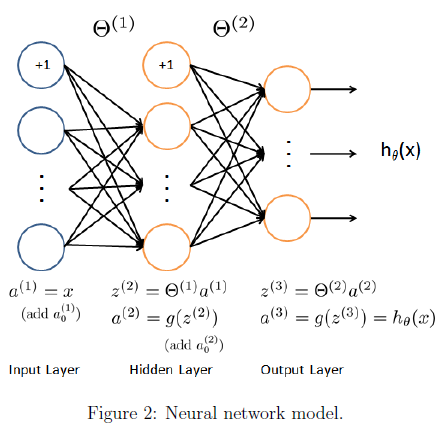

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

load('ex3data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

### 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);
% Predict
pred = predict(Theta1, Theta2, X(rp,:));
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

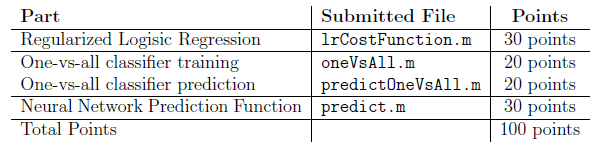

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.